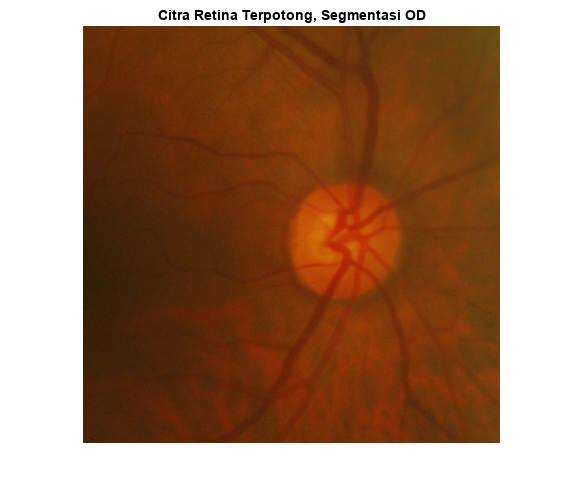

%Open file
[image, pathname] = uigetfile('*.png');
J = imread(image);

%Crop gambar untuk menghilangkan border hitam pada gambar asli
I = imcrop(J,[350 350 1250 1250]);
HSV = rgb2hsv(I);

%%Cek RGB
R = I(:,:,1)*1.2;
G = I(:,:,2)*1.2;
B = I(:,:,3)*1.2;

%figure, imshow(R)
%figure, imshow(G)
%figure, imshow(B)

%%Cek HSV
H = HSV(:,:,1);
S = HSV(:,:,2);
V = HSV(:,:,3);

figure, imshow(I)
title('Citra Retina Terpotong, Segmentasi OD')

%figure, imshow(H)
%figure, imshow(S)
%figure, imshow(V)

%Disimpulkan untuk lokalisasi dan segmentasi menggunakan nilai Value citra
%Ambil value citra
%Invert warna
%figure, imshow(imcomplement(adapthisteq(V)))
%Mengubah kontras citra gray
Vnew = imadjust(V) - imcomplement(V);
%figure, imshow(Vnew)
level = graythresh(V);
%Vnew = imadjust(Vnew);
ne = Vnew > level;
binaryImage = ne;
% Get rid of stuff touching the border
binaryImage = imclearborder(binaryImage);
fill = imfill(binaryImage,'holes');

se = strel('disk', 6)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


dil = imdilate(fill,se)

dil = 1251×1251 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

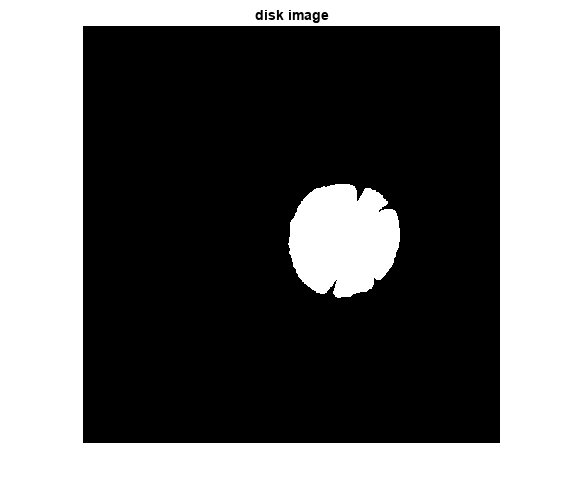

figure,imshow(dil)
title('disk image')


N = nnz(dil);
fprintf('Luas OD = %i Pixel\n', N)

Luas OD = 88467 Pixel



openim = imclose((imopen(dil, strel('diamond',25))), strel('arbitrary',40))

openim = 1251×1251 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

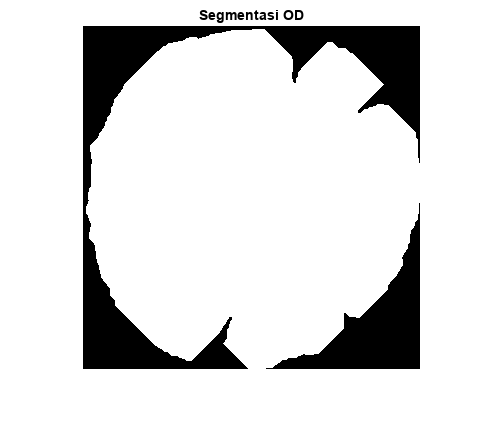

% Extract only the two largest blobs.
BW = binaryImage;
CC = bwconncomp(BW);
numPixels = cellfun(@numel,CC.PixelIdxList);
[biggest,idx] = max(numPixels);
BW(CC.PixelIdxList{idx}) = 0;
filteredForeground = BW;

% regionprops untuk mendapatkan informasi Area, Centroid, Bbox
s = regionprops(dil,'basic');
centroids = cat(1,s.Centroid);
bbox = cat(1,s.BoundingBox);
x = s(1).Centroid(1,1) - 1/2*(bbox(3));
y = s(1).Centroid(1,2) - 1/2*(bbox(4));
figure, imshow(imcrop(openim, [x y bbox(3) bbox(4)]))
title('Segmentasi OD')

fprintf('Panjang (x) Segmentasi = %i Pixel\n', bbox(3))

Panjang (x) Segmentasi = 336 Pixel


fprintf('Panjang (y) Segmentasi = %i Pixel\n', bbox(4))

Panjang (y) Segmentasi = 342 Pixel


fprintf('Titik Pusat = (%i, %i) Pixel\n', s(1).Centroid(1,1), s(1).Centroid(1,2));

Titik Pusat = (7.817083e+02, 6.415759e+02) Pixel


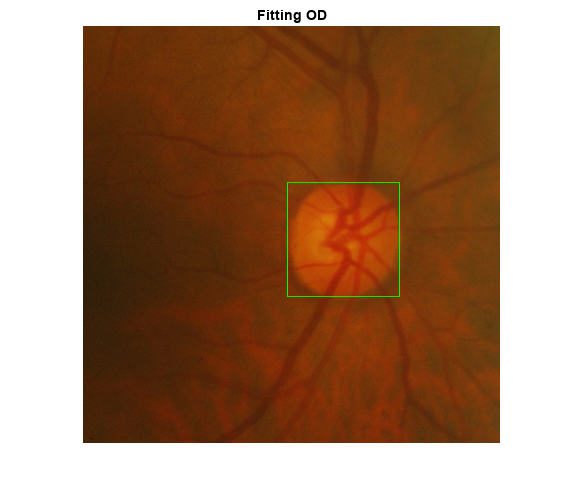


figure, imshow(I)
rectangle('Position',[x y bbox(3) bbox(4)],'EdgeColor','g')
title('Fitting OD')

%hold off
% Hitung Area, Luas BoundingBox, Titik tengah
fprintf('Area = %i Pixel\n', s(1).Area);

Area = 88467 Pixel


fprintf('Luas = %i Pixel^2\n', bbox(3)*bbox(4));

Luas = 114912 Pixel^2


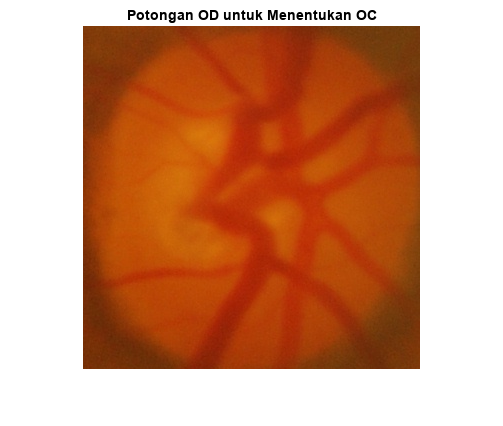


% figure, imshow(BW);
% % Fill holes in the blobs to make them solid.
%binaryImage = imfill(binaryImage, 'holes');
% % Display the binary image.
%dis(:,:,1)=immultiply(binaryImage,I(:,:,1));
%dis(:,:,2)=immultiply(binaryImage,I(:,:,2));
%dis(:,:,3)=immultiply(binaryImage,I(:,:,3));
%a = dil;
%stats = regionprops(double(a),'Centroid',...
%    'MajorAxisLength','MinorAxisLength')
%centers = stats.Centroid;
%diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
%radii = diameters/2;
% Plot the circles.
% figure,imshow(I)
%hold on
%viscircles(centers,radii);
%hold off

%Menentukan Luas OC
crpd = imcrop(I, [x y bbox(3) bbox(4)]);
figure, imshow(crpd)
title('Potongan OD untuk Menentukan OC');


%Invert warna
HSV = rgb2hsv(crpd);
V2 = HSV(:,:,3);

R2 = crpd(:,:,1);
G2 = crpd(:,:,2);
B2 = crpd(:,:,3);

%%FiltR2 = R2 - imcomplement(R2);
%%FiltG2 = G2 - imcomplement(G2);
%%FiltB2 = B2 - imcomplement(B2);

%figure, imshow(R2)
%figure, imshow(G2)
%%figure, imshow(B2)

%%figure, imshow(imadjust(FiltR2))
%%figure, imshow(FiltG2)
%%figure, imshow(FiltB2)
%%figure, imshow(G2 - imcomplement(G2))
%figure, imshow(imadjust(G2) - imcomplement(imadjust(G2)))

Test1 = G2 - imcomplement(G2);
Test2 = imadjust(G2) - imcomplement(imadjust(G2));
%%Test1 = R2 - imcomplement(R2);
%%Test2 = imadjust(R2) - imcomplement(imadjust(R2));
%%TestR1 = Test2 - Test1;
%%TestR2 = Test3 + Test4;
%%TestR3 = TestR1 + TestR2
TestR1 = Test2 - imcomplement(G2);
%figure, imshow(Test1)
%figure, imshow(Test2)
%%figure, imshow(Test3)
%%figure, imshow(Test4)
%figure, imshow(TestR1)
%%figure, imshow(TestR2)
%%figure, imshow(TestR3)


levelTR1 = graythresh(Test2);
neTR1 = imadjust(TestR1) > levelTR1;
binaryImage = neTR1;

%%figure, imshow(imcomplement(imadjust(V2)))
%Mengubah kontras citra gray
%%V2new = V2 - imcomplement(V2);
%%figure, imshow(V2new)
%%level2 = graythresh(V2);
%Vnew = imadjust(Vnew);
%%ne = V2new > level2;
%%binaryImage = ne;
% Get rid of stuff touching the border
binaryImage = imclearborder(binaryImage);
fill = imfill(binaryImage,'holes');

se = strel('disk', 8)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [15×15 logical]
    Dimensionality: 2


cup = imdilate(fill,se)

cup = 343×337 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

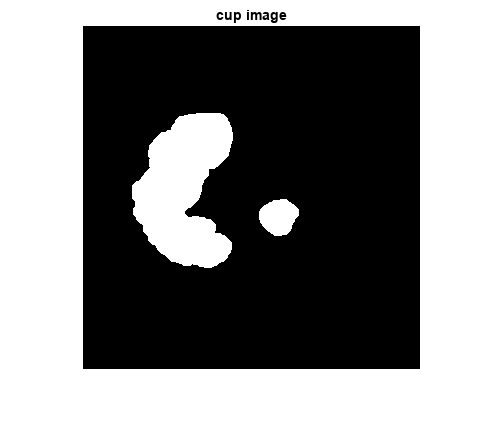

figure,imshow(cup)
title('cup image')


N = nnz(cup);
fprintf('Luas OC = %i Pixel\n', N)

Luas OC = 11421 Pixel



% regionprops untuk mendapatkan informasi Area, Centroid, Bbox
sc = regionprops(cup,'basic');
centroids = cat(1,sc.Centroid);
bboxc = cat(1,sc.BoundingBox);
xc = sc(1).Centroid(1,1) - 1/2*(bboxc(3));
yc = sc(1).Centroid(1,2) - 1/2*(bboxc(4));
fprintf('Panjang (x) Segmentasi = %i Pixel\n', bboxc(3))

Panjang (x) Segmentasi = 8.750000e+01 Pixel


fprintf('Panjang (y) Segmentasi = %i Pixel\n', bboxc(4))

Panjang (y) Segmentasi = 1.735000e+02 Pixel


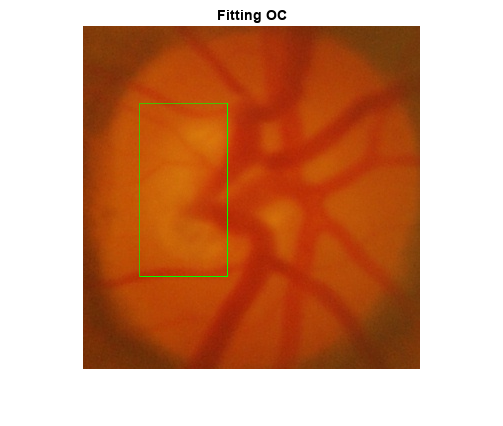


figure, imshow(crpd)
rectangle('Position',[xc yc bboxc(3) bboxc(4)],'EdgeColor','g')
title('Fitting OC')

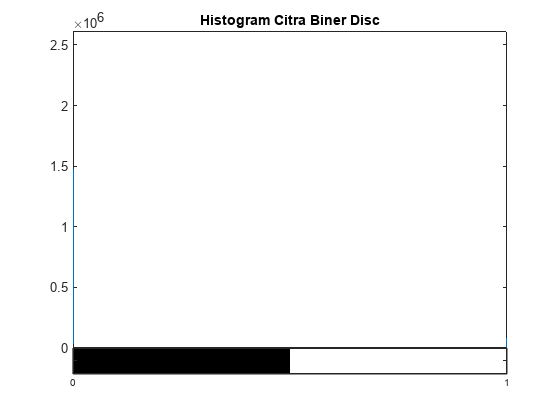


figure, imhist(dil)
title('Histogram Citra Biner Disc')

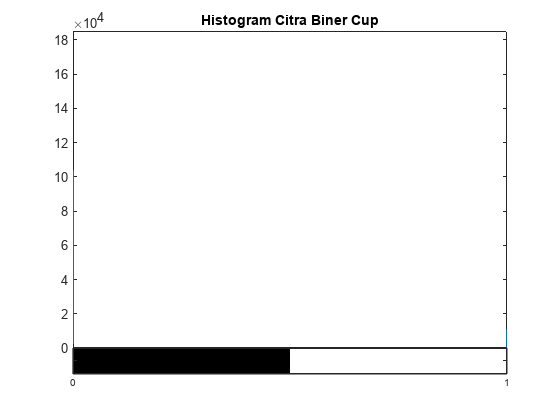

figure, imhist(cup)
title('Histogram Citra Biner Cup')